clc; clearvars; close all;

filePath1 = '..//..//stiletto_imuData//IMU1//datalog00002.TXT';
filePath2 = '..//..//stiletto_imuData//IMU2Or3//datalog00024.TXT';
filePath3 = '..//..//stiletto_imuData//IMU3Or2//datalog00013.TXT';
filePath4 = '..//..//stiletto_imuData//IMU4//datalog00004.TXT';

IMU1 = readtable(strcat(filePath1));

IMU2 = readtable(strcat(filePath2));

IMU3 = readtable(strcat(filePath3));

IMU4 = readtable(strcat(filePath4));

## Reformatting

% Making heading in terms of degrees
IMU1.gps_Heading = IMU1.gps_Heading / 100000;
IMU2.gps_Heading = IMU2.gps_Heading / 100000;
IMU3.gps_Heading = IMU3.gps_Heading / 100000;
IMU4.gps_Heading = IMU4.gps_Heading / 100000;

% t1 = string({'13:00:00.000'});
% t2 = string({'21:30:00.000'});

## Altitude

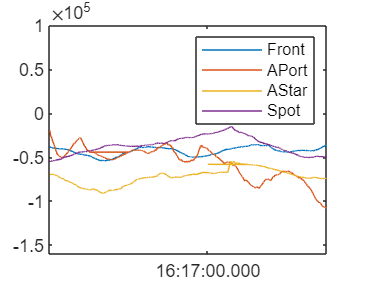

% Underway (10 kn)
figure
plot(IMU1.gps_Time,IMU1.gps_Alt, IMU2.gps_Time,IMU2.gps_Alt,...
     IMU3.gps_Time,IMU3.gps_Alt, IMU4.gps_Time,IMU4.gps_Alt)
uw1 = "16:13:00.000";
uw2 = "16:20:00.000";
uw1 = duration(uw1);
uw2 = duration(uw2);
xlim([uw1,uw2]);
ylim([-160000,100000,])
legend('Front','APort','AStar','Spot')

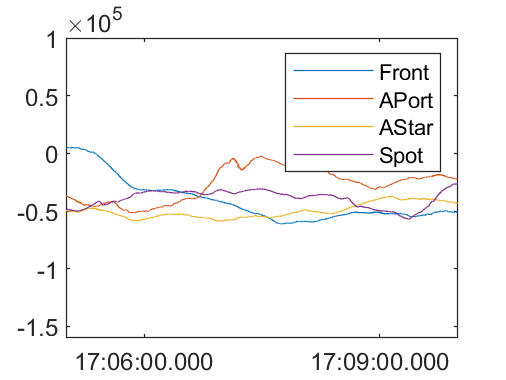

title("GPS Altitude: Underway (10 kn)")
xlabel("Time [hh:mm:ss.ttt]")
ylabel("Altitude [mm]")


% Seastate (20 kn)
figure
plot(IMU1.gps_Time,IMU1.gps_Alt, IMU2.gps_Time,IMU2.gps_Alt,...
     IMU3.gps_Time,IMU3.gps_Alt, IMU4.gps_Time,IMU4.gps_Alt)
ss1 = "17:05:00.000";
ss2 = "17:10:00.000";
ss1 = duration(ss1);
ss2 = duration(ss2);
xlim([ss1,ss2]);
ylim([-160000,100000,])
legend('Front','APort','AStar','Spot')

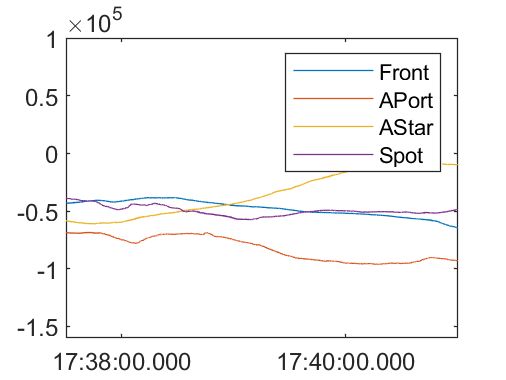

title("GPS Altitude: Sea State (20 kn)")
xlabel("Time [hh:mm:ss.ttt]")
ylabel("Altitude [mm]")

% S-Curves (20 kn)
figure
plot(IMU1.gps_Time,IMU1.gps_Alt, IMU2.gps_Time,IMU2.gps_Alt,...
     IMU3.gps_Time,IMU3.gps_Alt, IMU4.gps_Time,IMU4.gps_Alt)
sc1 = "17:37:30.000";
sc2 = "17:41:00.000";
sc1 = duration(sc1);
sc2 = duration(sc2);
xlim([sc1,sc2]);
ylim([-160000,100000,])

legend('Front','APort','AStar','Spot')
title("GPS Altitude: S-Curves (20 kn)")
xlabel("Time [hh:mm:ss.ttt]")
ylabel("Altitude [mm]")


## Heading

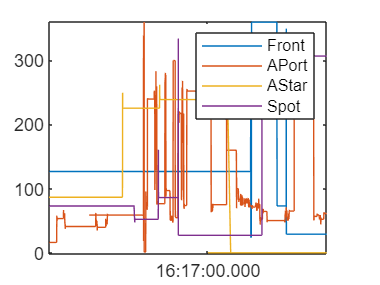

% t1 = string({'19:22:05.000'});
% t2 = string({'19:33:30.000'});
% t1 = string({'19:25:00.000'});
% t2 = string({'19:26:00.000'});
% t1 = duration(t1);
% t2 = duration(t2);

figure
plot(IMU1.gps_Time,IMU1.gps_Heading, IMU2.gps_Time,IMU2.gps_Heading,...
     IMU3.gps_Time,IMU3.gps_Heading, IMU4.gps_Time,IMU4.gps_Heading)
xlim([uw1,uw2]);
ylim([-1,361,])
legend('Front','APort','AStar','Spot')

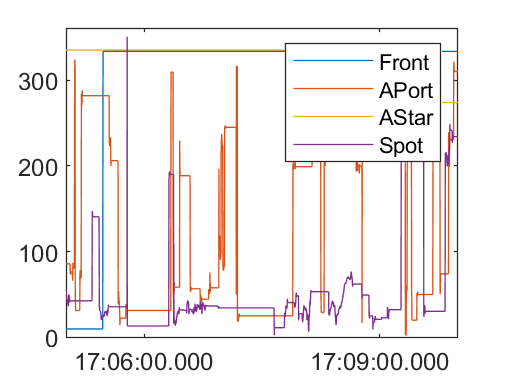


figure
plot(IMU1.gps_Time,IMU1.gps_Heading, IMU2.gps_Time,IMU2.gps_Heading,...
     IMU3.gps_Time,IMU3.gps_Heading, IMU4.gps_Time,IMU4.gps_Heading)
xlim([ss1,ss2]);
ylim([-1,361,])
legend('Front','APort','AStar','Spot')

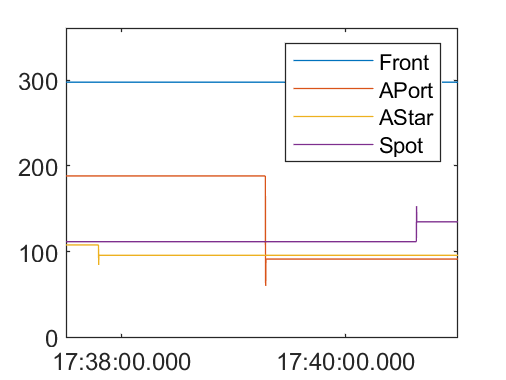


figure
plot(IMU1.gps_Time,IMU1.gps_Heading, IMU2.gps_Time,IMU2.gps_Heading,...
     IMU3.gps_Time,IMU3.gps_Heading, IMU4.gps_Time,IMU4.gps_Heading)
xlim([sc1,sc2]);
ylim([-1,361,])
legend('Front','APort','AStar','Spot')

## Longitude

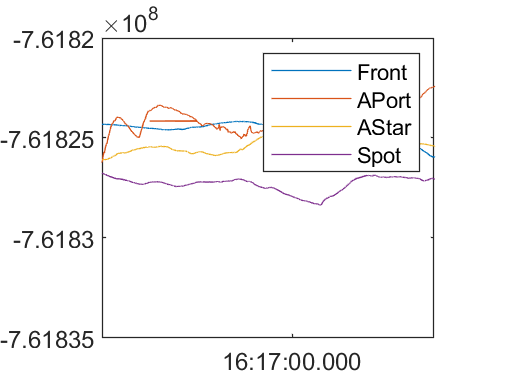

% t1 = string({'14:40:00.000'});
% t2 = string({'19:07:00.000'});
% t1 = duration(t1);
% t2 = duration(t2);

figure
plot(IMU1.gps_Time,IMU1.gps_Long, IMU2.gps_Time,IMU2.gps_Long,...
     IMU3.gps_Time,IMU3.gps_Long, IMU4.gps_Time,IMU4.gps_Long)
xlim([uw1,uw2]);
ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

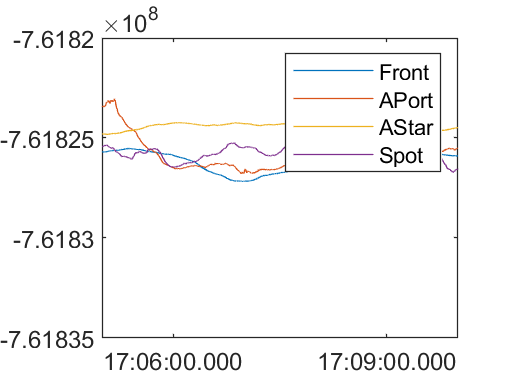


figure
plot(IMU1.gps_Time,IMU1.gps_Long, IMU2.gps_Time,IMU2.gps_Long,...
     IMU3.gps_Time,IMU3.gps_Long, IMU4.gps_Time,IMU4.gps_Long)
xlim([ss1,ss2]);
ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

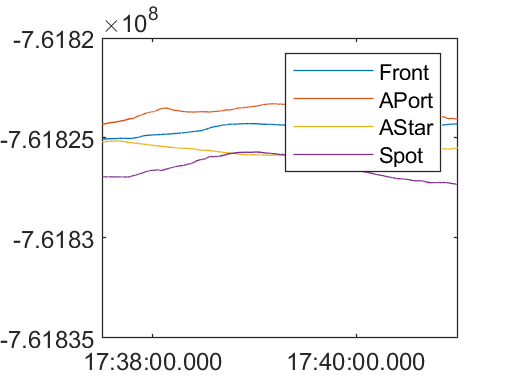


figure
plot(IMU1.gps_Time,IMU1.gps_Long, IMU2.gps_Time,IMU2.gps_Long,...
     IMU3.gps_Time,IMU3.gps_Long, IMU4.gps_Time,IMU4.gps_Long)
xlim([sc1,sc2]);
ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

## Latitude

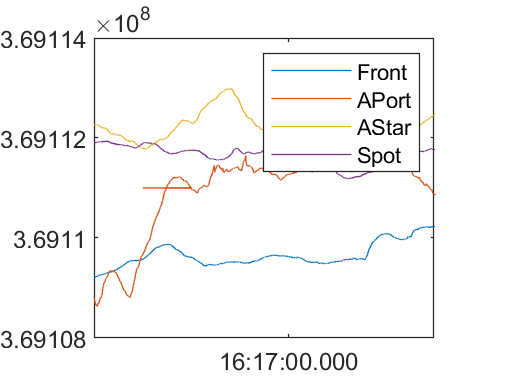

% t1 = string({'14:40:00.000'});
% t2 = string({'19:07:00.000'});
% t1 = duration(t1);
% t2 = duration(t2);

figure
plot(IMU1.gps_Time,IMU1.gps_Lat, IMU2.gps_Time,IMU2.gps_Lat,...
     IMU3.gps_Time,IMU3.gps_Lat, IMU4.gps_Time,IMU4.gps_Lat)
xlim([uw1,uw2]);
% ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

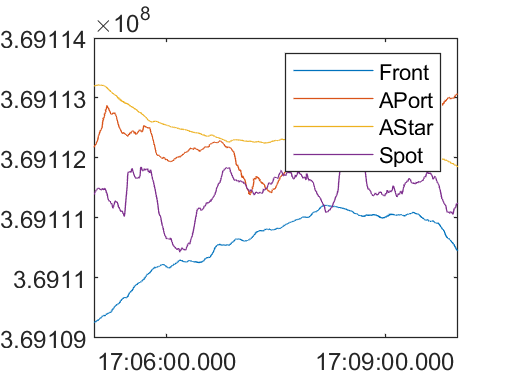


figure
plot(IMU1.gps_Time,IMU1.gps_Lat, IMU2.gps_Time,IMU2.gps_Lat,...
     IMU3.gps_Time,IMU3.gps_Lat, IMU4.gps_Time,IMU4.gps_Lat)
xlim([ss1,ss2]);
% ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

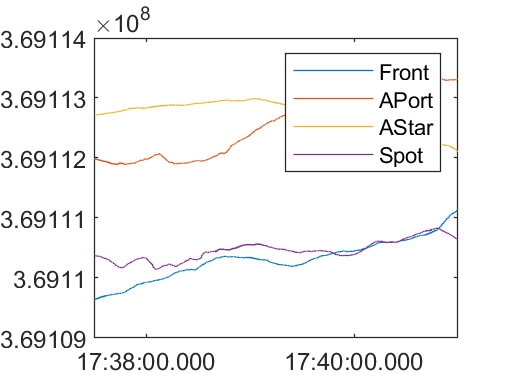


figure
plot(IMU1.gps_Time,IMU1.gps_Lat, IMU2.gps_Time,IMU2.gps_Lat,...
     IMU3.gps_Time,IMU3.gps_Lat, IMU4.gps_Time,IMU4.gps_Lat)
xlim([sc1,sc2]);
% ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

## Find Timestamp Index

## IMU 1

uw1_imu1_i = 0;     uw2_imu1_i = 0;
ss1_imu1_i = 0;     ss2_imu1_i = 0;
sc1_imu1_i = 0;     sc2_imu1_i = 0;

for i = 1:size(IMU1.gps_Time)
    % Underway
    if uw1_imu1_i == 0
        if IMU1.gps_Time(i) >= uw1
            uw1_imu1_i = i;
        end
    end
    if uw2_imu1_i == 0
        if IMU1.gps_Time(i) >= uw2
            uw2_imu1_i = i;
        end
    end

    % Sea State
    if ss1_imu1_i == 0
        if IMU1.gps_Time(i) >= ss1
            ss1_imu1_i = i;
        end
    end
    if ss2_imu1_i == 0
        if IMU1.gps_Time(i) >= ss2
            ss2_imu1_i = i;
        end
    end

    % S-Curves
    if sc1_imu1_i == 0
        if IMU1.gps_Time(i) >= sc1
            sc1_imu1_i = i;
        end
    end
    if sc2_imu1_i == 0
        if IMU1.gps_Time(i) >= sc2
            sc2_imu1_i = i;
        end
    end
end


## IMU 2

uw1_imu2_i = 0;     uw2_imu2_i = 0;
ss1_imu2_i = 0;     ss2_imu2_i = 0;
sc1_imu2_i = 0;     sc2_imu2_i = 0;

for i = 1:size(IMU2.gps_Time)
    % Underway
    if uw1_imu2_i == 0
        if IMU2.gps_Time(i) >= uw1
            uw1_imu2_i = i;
        end
    end
    if uw2_imu2_i == 0
        if IMU2.gps_Time(i) >= uw2
            uw2_imu2_i = i;
        end
    end

    % Sea State
    if ss1_imu2_i == 0
        if IMU2.gps_Time(i) >= ss1
            ss1_imu2_i = i;
        end
    end
    if ss2_imu2_i == 0
        if IMU2.gps_Time(i) >= ss2
            ss2_imu2_i = i;
        end
    end

    % S-Curves
    if sc1_imu2_i == 0
        if IMU2.gps_Time(i) >= sc1
            sc1_imu2_i = i;
        end
    end
    if sc2_imu2_i == 0
        if IMU2.gps_Time(i) >= sc2
            sc2_imu2_i = i;
        end
    end
end

## IMU 3

uw1_imu3_i = 0;     uw2_imu3_i = 0;
ss1_imu3_i = 0;     ss2_imu3_i = 0;
sc1_imu3_i = 0;     sc2_imu3_i = 0;

for i = 1:size(IMU3.gps_Time)
    % Underway
    if uw1_imu3_i == 0
        if IMU3.gps_Time(i) >= uw1
            uw1_imu3_i = i;
        end
    end
    if uw2_imu3_i == 0
        if IMU3.gps_Time(i) >= uw2
            uw2_imu3_i = i;
        end
    end

    % Sea State
    if ss1_imu3_i == 0
        if IMU3.gps_Time(i) >= ss1
            ss1_imu3_i = i;
        end
    end
    if ss2_imu3_i == 0
        if IMU3.gps_Time(i) >= ss2
            ss2_imu3_i = i;
        end
    end

    % S-Curves
    if sc1_imu3_i == 0
        if IMU3.gps_Time(i) >= sc1
            sc1_imu3_i = i;
        end
    end
    if sc2_imu3_i == 0
        if IMU3.gps_Time(i) >= sc2
            sc2_imu3_i = i;
        end
    end
end

## IMU 4

uw1_imu4_i = 0;     uw2_imu4_i = 0;
ss1_imu4_i = 0;     ss2_imu4_i = 0;
sc1_imu4_i = 0;     sc2_imu4_i = 0;

for i = 1:size(IMU4.gps_Time)
    % Underway
    if uw1_imu4_i == 0
        if IMU4.gps_Time(i) >= uw1
            uw1_imu4_i = i;
        end
    end
    if uw2_imu4_i == 0
        if IMU4.gps_Time(i) >= uw2
            uw2_imu4_i = i;
        end
    end

    % Sea State
    if ss1_imu4_i == 0
        if IMU4.gps_Time(i) >= ss1
            ss1_imu4_i = i;
        end
    end
    if ss2_imu4_i == 0
        if IMU4.gps_Time(i) >= ss2
            ss2_imu4_i = i;
        end
    end

    % S-Curves
    if sc1_imu4_i == 0
        if IMU4.gps_Time(i) >= sc1
            sc1_imu4_i = i;
        end
    end
    if sc2_imu4_i == 0
        if IMU4.gps_Time(i) >= sc2
            sc2_imu4_i = i;
        end
    end
end


## IMU Accel -> Disp

%IMU1_Disp.x = accel2disp(IMU1.aX, 10)

## Lat & Long Euclidean

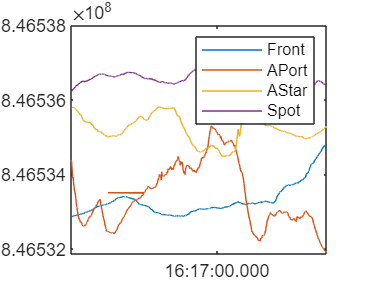

IMU1_dist = euclidean(IMU1.gps_Lat, IMU1.gps_Long);
IMU2_dist = euclidean(IMU2.gps_Lat, IMU2.gps_Long);
IMU3_dist = euclidean(IMU3.gps_Lat, IMU3.gps_Long);
IMU4_dist = euclidean(IMU4.gps_Lat, IMU4.gps_Long);


figure
plot(IMU1.gps_Time,IMU1_dist, IMU2.gps_Time,IMU2_dist,...
     IMU3.gps_Time,IMU3_dist, IMU4.gps_Time,IMU4_dist)
xlim([uw1,uw2]);
% ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

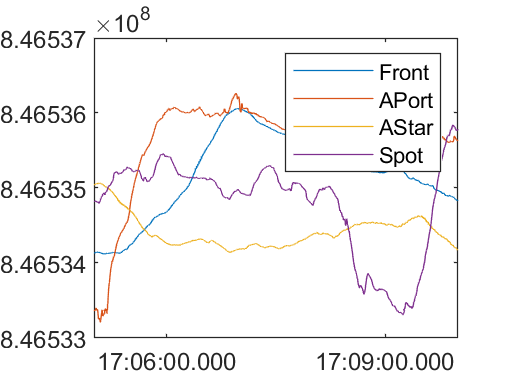


figure
plot(IMU1.gps_Time,IMU1_dist, IMU2.gps_Time,IMU2_dist,...
     IMU3.gps_Time,IMU3_dist, IMU4.gps_Time,IMU4_dist)
xlim([ss1,ss2]);
% ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

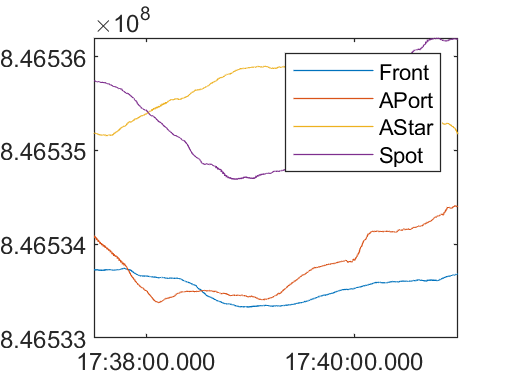


figure
plot(IMU1.gps_Time,IMU1_dist, IMU2.gps_Time,IMU2_dist,...
     IMU3.gps_Time,IMU3_dist, IMU4.gps_Time,IMU4_dist)
xlim([sc1,sc2]);
% ylim([-7.61835e8,-7.6182e8])
legend('Front','APort','AStar','Spot')

## Distance Change

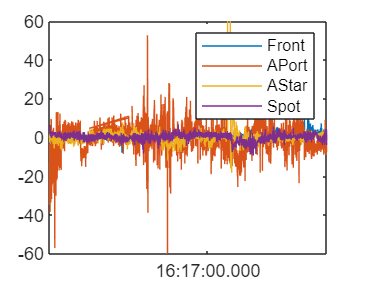

IMU1_dDist = dDist(IMU1_dist);
IMU2_dDist = dDist(IMU2_dist);
IMU3_dDist = dDist(IMU3_dist);
IMU4_dDist = dDist(IMU4_dist);

figure
plot(IMU1.gps_Time,IMU1_dDist, IMU2.gps_Time,IMU2_dDist,...
     IMU3.gps_Time,IMU3_dDist, IMU4.gps_Time,IMU4_dDist)
xlim([uw1,uw2]);
ylim([-60,60])
legend('Front','APort','AStar','Spot')

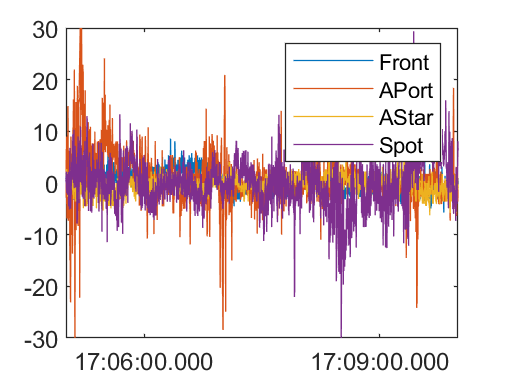


figure
plot(IMU1.gps_Time,IMU1_dDist, IMU2.gps_Time,IMU2_dDist,...
     IMU3.gps_Time,IMU3_dDist, IMU4.gps_Time,IMU4_dDist)
xlim([ss1,ss2]);
ylim([-30,30])
legend('Front','APort','AStar','Spot')

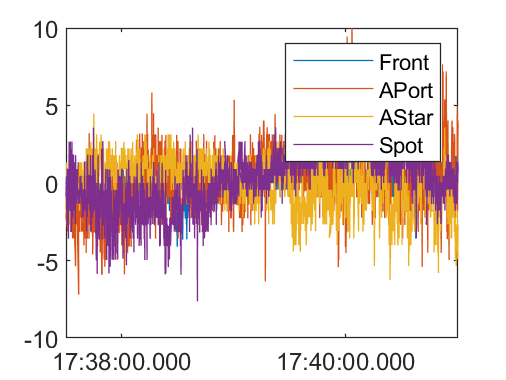


figure
plot(IMU1.gps_Time,IMU1_dDist, IMU2.gps_Time,IMU2_dDist,...
     IMU3.gps_Time,IMU3_dDist, IMU4.gps_Time,IMU4_dDist)
xlim([sc1,sc2]);
ylim([-10, 10])
legend('Front','APort','AStar','Spot')

## Height Change

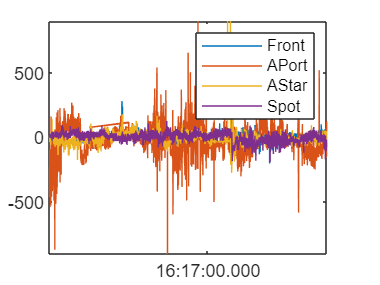

IMU1_dAlt = dDist(IMU1.gps_Alt);
IMU2_dAlt = dDist(IMU2.gps_Alt);
IMU3_dAlt = dDist(IMU3.gps_Alt);
IMU4_dAlt = dDist(IMU4.gps_Alt);

figure
plot(IMU1.gps_Time,IMU1_dAlt, IMU2.gps_Time,IMU2_dAlt,...
     IMU3.gps_Time,IMU3_dAlt, IMU4.gps_Time,IMU4_dAlt)
xlim([uw1,uw2]);
ylim([-900,900])
legend('Front','APort','AStar','Spot')

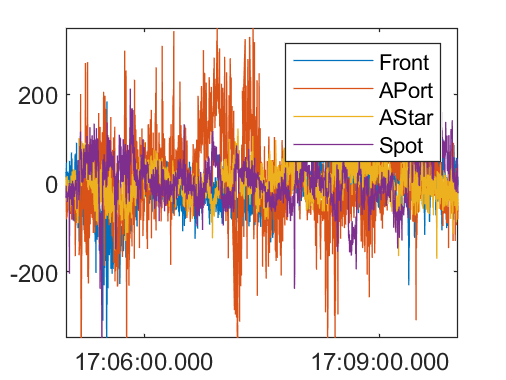


figure
plot(IMU1.gps_Time,IMU1_dAlt, IMU2.gps_Time,IMU2_dAlt,...
     IMU3.gps_Time,IMU3_dAlt, IMU4.gps_Time,IMU4_dAlt)
xlim([ss1,ss2]);
ylim([-350,350])
legend('Front','APort','AStar','Spot')

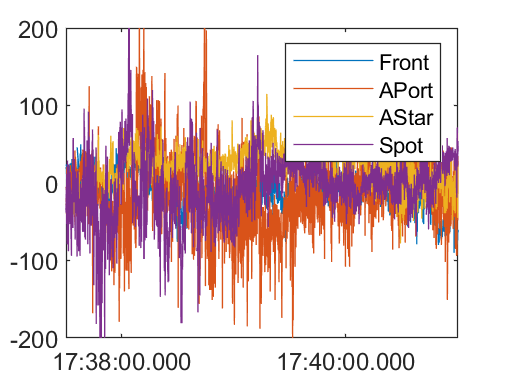


figure
plot(IMU1.gps_Time,IMU1_dAlt, IMU2.gps_Time,IMU2_dAlt,...
     IMU3.gps_Time,IMU3_dAlt, IMU4.gps_Time,IMU4_dAlt)
xlim([sc1,sc2]);
ylim([-200, 200])
legend('Front','APort','AStar','Spot')

## Extract IMU Data from Timestamps

% Altitude
% Underway
[IMU1_UW_dAlt, IMU1_UW_time] = extract(IMU1_dAlt, IMU1.gps_Time, uw1_imu1_i, uw2_imu1_i);
[IMU2_UW_dAlt, IMU2_UW_time] = extract(IMU2_dAlt, IMU2.gps_Time, uw1_imu2_i, uw2_imu2_i);
[IMU3_UW_dAlt, IMU3_UW_time] = extract(IMU3_dAlt, IMU3.gps_Time, uw1_imu3_i, uw2_imu3_i);
[IMU4_UW_dAlt, IMU4_UW_time] = extract(IMU4_dAlt, IMU4.gps_Time, uw1_imu4_i, uw2_imu4_i);

% Sea State
[IMU1_SS_dAlt, IMU1_SS_time] = extract(IMU1_dAlt, IMU1.gps_Time, ss1_imu1_i, ss2_imu1_i);
[IMU2_SS_dAlt, IMU2_SS_time] = extract(IMU2_dAlt, IMU2.gps_Time, ss1_imu2_i, ss2_imu2_i);
[IMU3_SS_dAlt, IMU3_SS_time] = extract(IMU3_dAlt, IMU3.gps_Time, ss1_imu3_i, ss2_imu3_i);
[IMU4_SS_dAlt, IMU4_SS_time] = extract(IMU4_dAlt, IMU4.gps_Time, ss1_imu4_i, ss2_imu4_i);

% S_Curves
[IMU1_SC_dAlt, IMU1_SC_time] = extract(IMU1_dAlt, IMU1.gps_Time, sc1_imu1_i, sc2_imu1_i);
[IMU2_SC_dAlt, IMU2_SC_time] = extract(IMU2_dAlt, IMU2.gps_Time, sc1_imu2_i, sc2_imu2_i);
[IMU3_SC_dAlt, IMU3_SC_time] = extract(IMU3_dAlt, IMU3.gps_Time, sc1_imu3_i, sc2_imu3_i);
[IMU4_SC_dAlt, IMU4_SC_time] = extract(IMU4_dAlt, IMU4.gps_Time, sc1_imu4_i, sc2_imu4_i);

% Distance
% Underway
[IMU1_UW_dDist, ~] = extract(IMU1_dDist, IMU1.gps_Time, uw1_imu1_i, uw2_imu1_i);
[IMU2_UW_dDist, ~] = extract(IMU2_dDist, IMU2.gps_Time, uw1_imu2_i, uw2_imu2_i);
[IMU3_UW_dDist, ~] = extract(IMU3_dDist, IMU3.gps_Time, uw1_imu3_i, uw2_imu3_i);
[IMU4_UW_dDist, ~] = extract(IMU4_dDist, IMU4.gps_Time, uw1_imu4_i, uw2_imu4_i);

% Sea State
[IMU1_SS_dDist, ~] = extract(IMU1_dDist, IMU1.gps_Time, ss1_imu1_i, ss2_imu1_i);
[IMU2_SS_dDist, ~] = extract(IMU2_dDist, IMU2.gps_Time, ss1_imu2_i, ss2_imu2_i);
[IMU3_SS_dDist, ~] = extract(IMU3_dDist, IMU3.gps_Time, ss1_imu3_i, ss2_imu3_i);
[IMU4_SS_dDist, ~] = extract(IMU4_dDist, IMU4.gps_Time, ss1_imu4_i, ss2_imu4_i);

% S_Curves
[IMU1_SC_dDist, ~] = extract(IMU1_dDist, IMU1.gps_Time, sc1_imu1_i, sc2_imu1_i);
[IMU2_SC_dDist, ~] = extract(IMU2_dDist, IMU2.gps_Time, sc1_imu2_i, sc2_imu2_i);
[IMU3_SC_dDist, ~] = extract(IMU3_dDist, IMU3.gps_Time, sc1_imu3_i, sc2_imu3_i);
[IMU4_SC_dDist, ~] = extract(IMU4_dDist, IMU4.gps_Time, sc1_imu4_i, sc2_imu4_i);

## FFT Equations

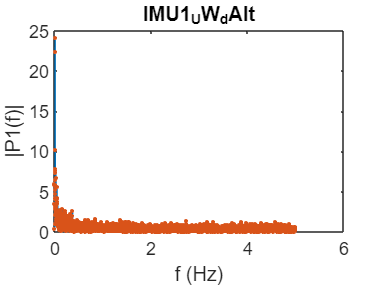

% Altitude
[uw1A_u,uw1A_uf] = plotFFT(IMU1_UW_dAlt, 10, 'IMU1_UW_dAlt');   % 5 above 5

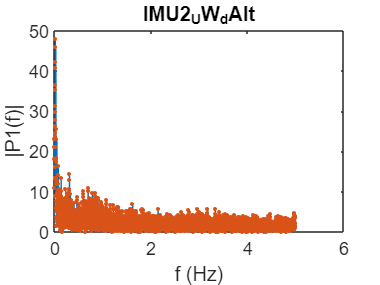

[uw2A_u,uw2A_uf] = plotFFT(IMU2_UW_dAlt, 10, 'IMU2_UW_dAlt');   % 4 above 25, 9 above 20

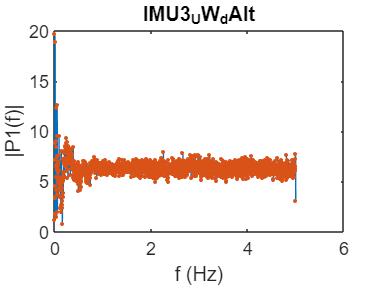

[uw3A_u,uw3A_uf] = plotFFT(IMU3_UW_dAlt, 10, 'IMU3_UW_dAlt');   % 4 above 10

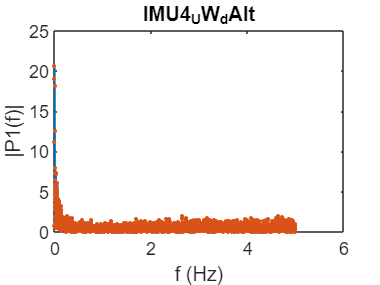

[uw4A_u,uw4A_uf] = plotFFT(IMU4_UW_dAlt, 10, 'IMU4_UW_dAlt');   

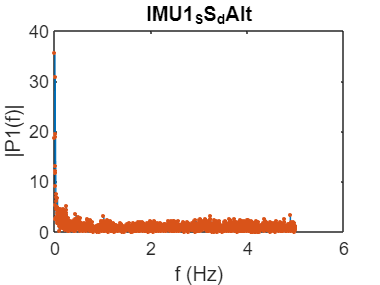


[ss1A_u,ss1A_uf] = plotFFT(IMU1_SS_dAlt, 10, 'IMU1_SS_dAlt');   % 6 above 10

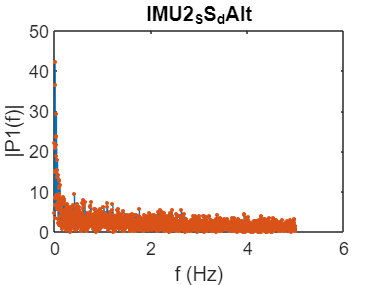

[ss2A_u,ss2A_uf] = plotFFT(IMU2_SS_dAlt, 10, 'IMU2_SS_dAlt');   % 7 above 20

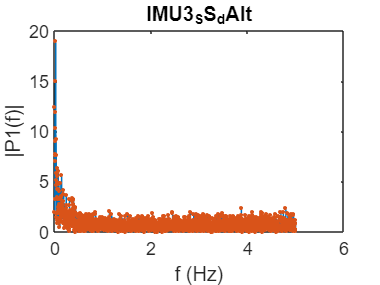

[ss3A_u,ss3A_uf] = plotFFT(IMU3_SS_dAlt, 10, 'IMU3_SS_dAlt');   % 4 above 8

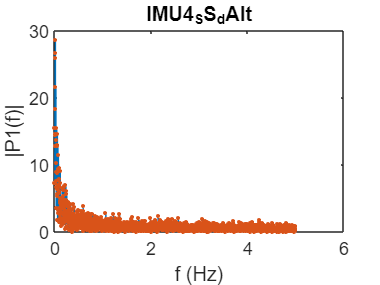

[ss4A_u,ss4A_uf] = plotFFT(IMU4_SS_dAlt, 10, 'IMU4_SS_dAlt');   

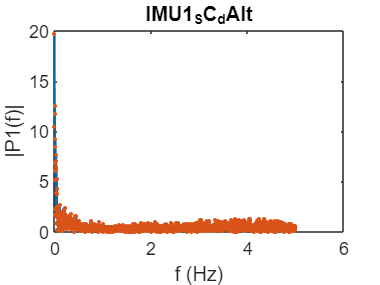


[sc1A_u,sc1A_uf] = plotFFT(IMU1_SC_dAlt, 10, 'IMU1_SC_dAlt');   % 3 above 8, 8 above 6

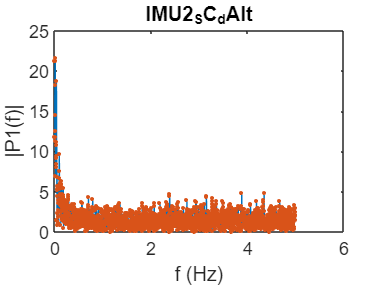

[sc2A_u,sc2A_uf] = plotFFT(IMU2_SC_dAlt, 10, 'IMU2_SC_dAlt');   % 5 above 12

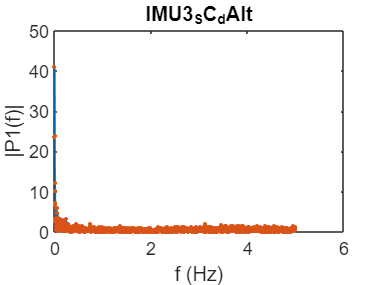

[sc3A_u,sc3A_uf] = plotFFT(IMU3_SC_dAlt, 10, 'IMU3_SC_dAlt');   % 3 above 10

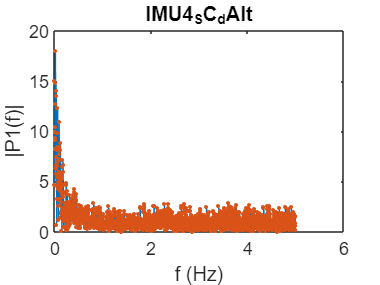

[sc4A_u,sc4A_uf] = plotFFT(IMU4_SC_dAlt, 10, 'IMU4_SC_dAlt');

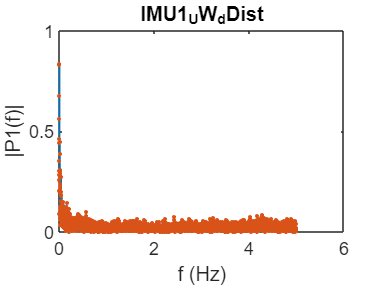


% Distance
[uw1D_u,uw1D_uf] = plotFFT(IMU1_UW_dDist, 10, 'IMU1_UW_dDist'); % 3 above 0.4

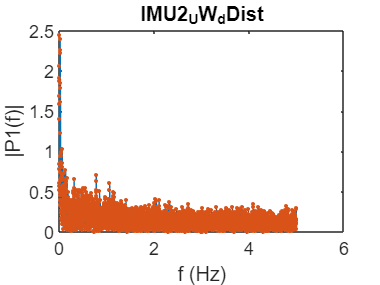

[uw2D_u,uw2D_uf] = plotFFT(IMU2_UW_dDist, 10, 'IMU2_UW_dDist'); % 8 above 1

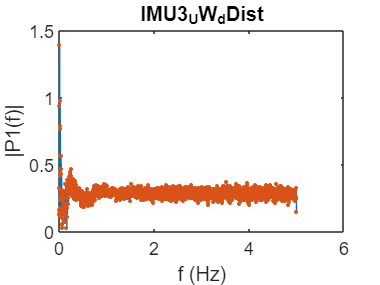

[uw3D_u,uw3D_uf] = plotFFT(IMU3_UW_dDist, 10, 'IMU3_UW_dDist'); % 5 above 0.6

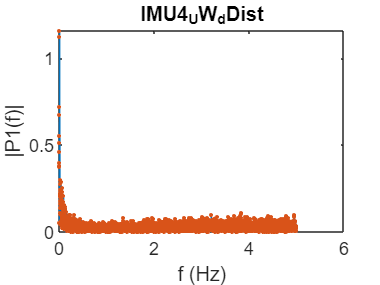

[uw4D_u,uw4D_uf] = plotFFT(IMU4_UW_dDist, 10, 'IMU4_UW_dDist');

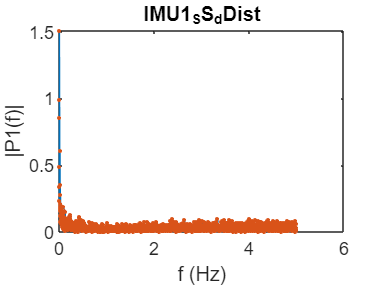


[ss1D_u,ss1D_uf] = plotFFT(IMU1_SS_dDist, 10, 'IMU1_SS_dDist'); % 3 above 0.6

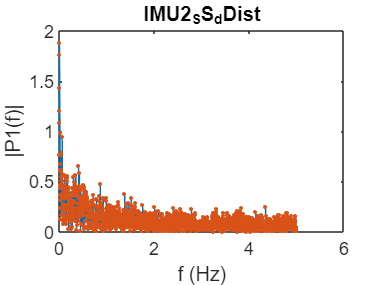

[ss2D_u,ss2D_uf] = plotFFT(IMU2_SS_dDist, 10, 'IMU2_SS_dDist'); % 5 above 0.8, 3 above 1.2

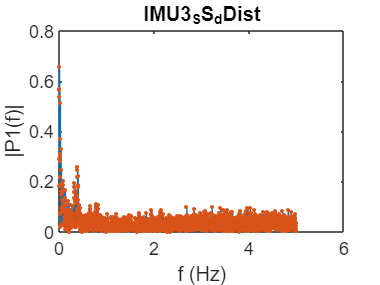

[ss3D_u,ss3D_uf] = plotFFT(IMU3_SS_dDist, 10, 'IMU3_SS_dDist'); % 2 above 0.4, 5 above 0.2

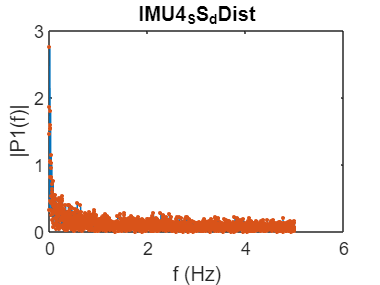

[ss4D_u,ss4D_uf] = plotFFT(IMU4_SS_dDist, 10, 'IMU4_SS_dDist');

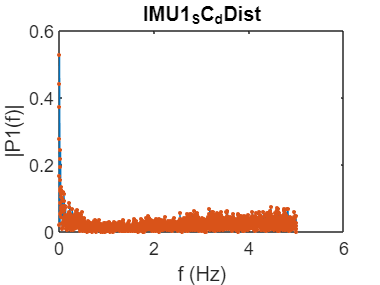


[sc1D_u,sc1D_uf] = plotFFT(IMU1_SC_dDist, 10, 'IMU1_SC_dDist'); % 3 above 0.2

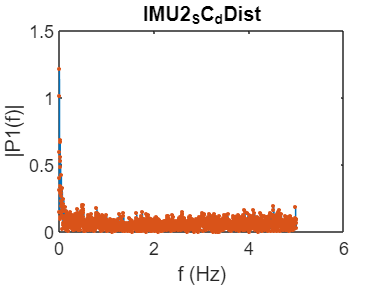

[sc2D_u,sc2D_uf] = plotFFT(IMU2_SC_dDist, 10, 'IMU2_SC_dDist'); % 3 above 0.6

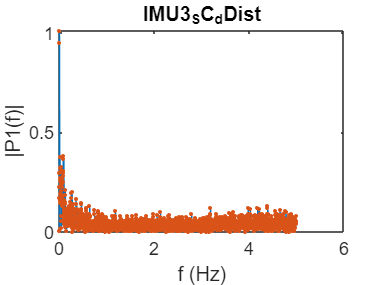

[sc3D_u,sc3D_uf] = plotFFT(IMU3_SC_dDist, 10, 'IMU3_SC_dDist'); % 5 above 0.3

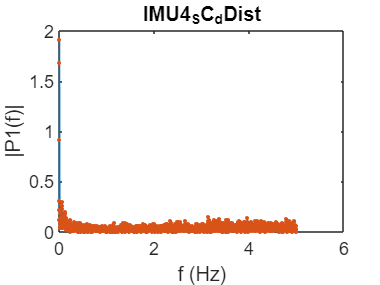

[sc4D_u,sc4D_uf] = plotFFT(IMU4_SC_dDist, 10, 'IMU4_SC_dDist');

## Filtered FFT

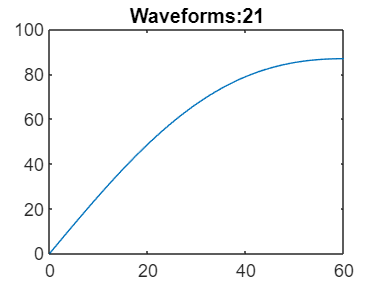

% Altitude
% Underway
uw1A_f = filter(uw1A_u, uw1A_uf, 4);

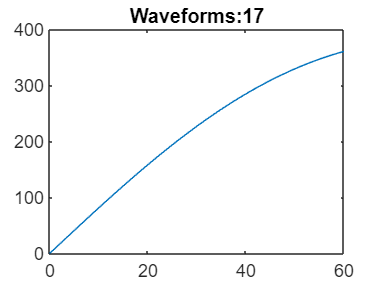

uw2A_f = filter(uw2A_u, uw2A_uf, 20);

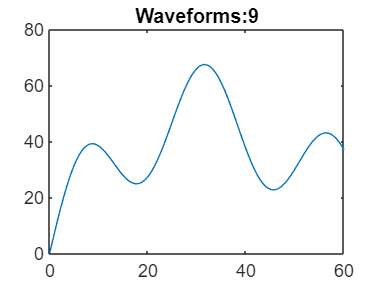

uw3A_f = filter(uw3A_u, uw3A_uf, 9);

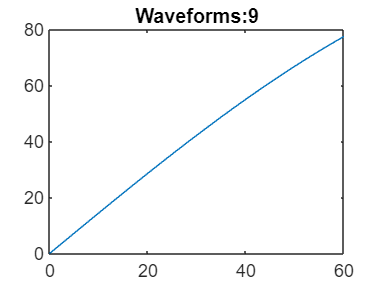


% Sea State
ss1A_f = filter(ss1A_u, ss1A_uf, 9);

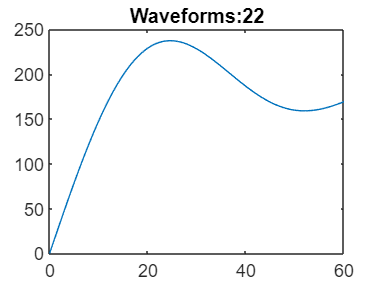

ss2A_f = filter(ss2A_u, ss2A_uf, 10);

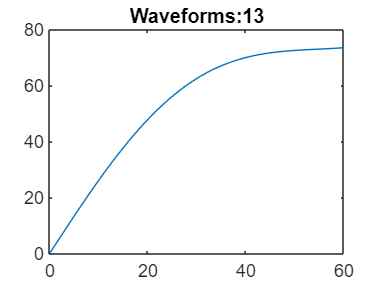

ss3A_f = filter(ss3A_u, ss3A_uf, 6);

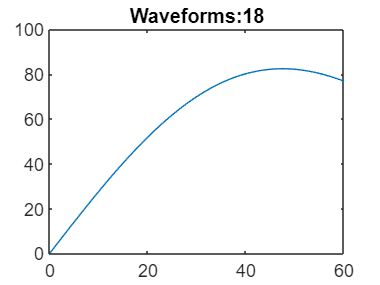


% S-Curve
sc1A_f = filter(sc1A_u, sc1A_uf, 3.5);

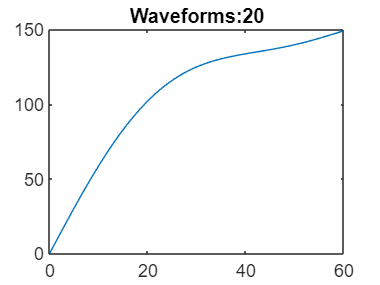

sc2A_f = filter(sc2A_u, sc2A_uf, 7);

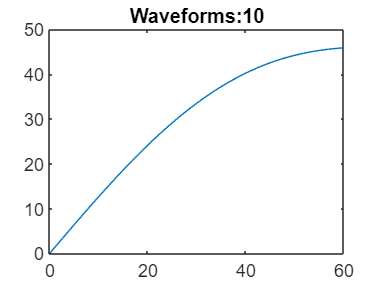

sc3A_f = filter(sc3A_u, sc3A_uf, 5);

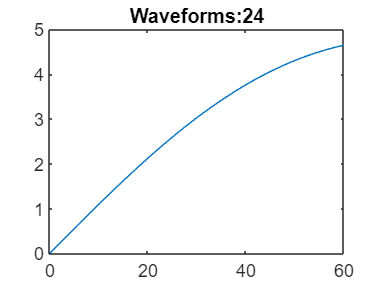


% Distance
% Underway
uw1D_f = filter(uw1D_u, uw1D_uf, 0.2);

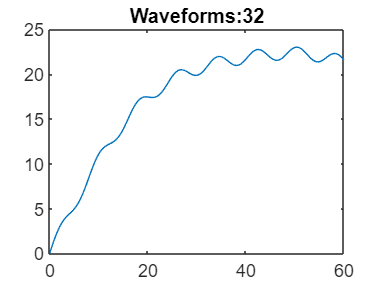

uw2D_f = filter(uw2D_u, uw2D_uf, 0.7);

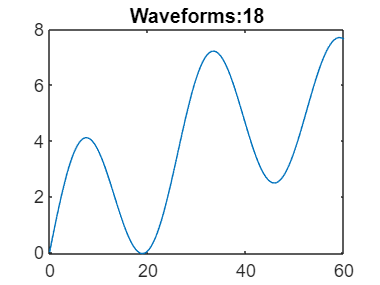

uw3D_f = filter(uw3D_u, uw3D_uf, 0.4);

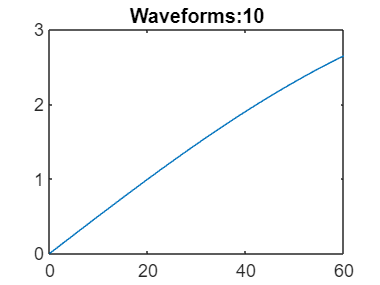


% Sea State
ss1D_f = filter(ss1D_u, ss1D_uf, 0.2);

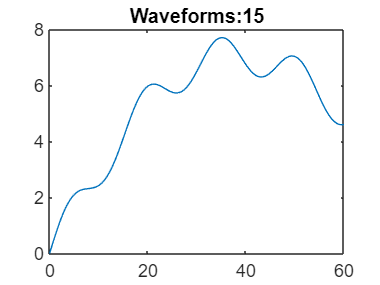

ss2D_f = filter(ss2D_u, ss2D_uf, 0.6);

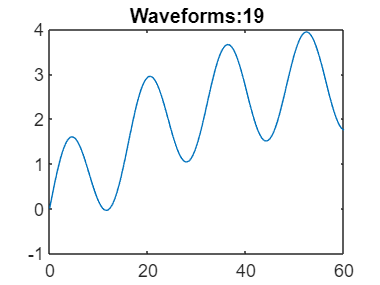

ss3D_f = filter(ss3D_u, ss3D_uf, 0.2);

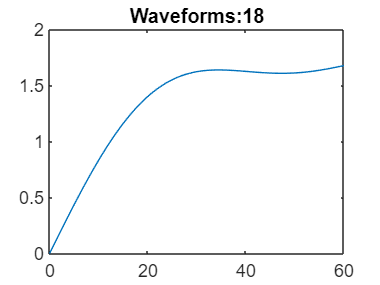


% S-Curve
sc1D_f = filter(sc1D_u, sc1D_uf, 0.1);

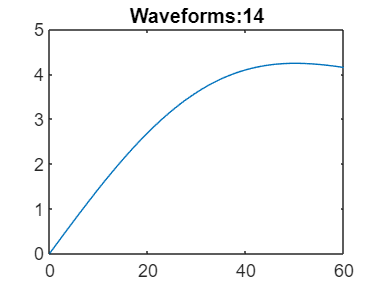

sc2D_f = filter(sc2D_u, sc2D_uf, 0.3);

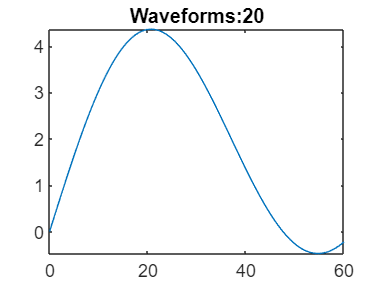

sc3D_f = filter(sc3D_u, sc3D_uf, 0.25);

function dist = euclidean(lat, long)
    dist = zeros(size(lat,1),1);
    
    for i = 1:size(lat)
        dist(i) = sqrt(lat(i)^2 + long(i)^2);
    end
end


function ddist = dDist(dist)
    ddist = zeros(size(dist,1),1) - 1;
    
    for i = 1:size(dist)-1
        ddist(i) = dist(i+1) - dist(i);
    end
end


function [data, time] = extract(IMU_data, IMU_time, i1, i2)
    index = (i2 - i1 + 1);
    data = zeros(index,1);

    for i = 1:index
        data(i) = IMU_data((i1-1)+i);
        time(i) = IMU_time((i1-1)+i);
    end
    time = time';
end


function [P1,f] = plotFFT(X, Fs, dataTitle)
    L = size(X,1);
n = 2^nextpow2(L);
%     Y = fft(X);
Y = fft(X,n);
    
    P2 = abs(Y/L);
%     P1 = P2(1:L/2+1);
P1 = P2(1:n/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    ave = mean(P1);
    RMS = rms(P1);

%     f = Fs*(0:(L/2))/L;
f = Fs*(0:(n/2))/n;
    plot(f,P1, f,P1, '.') 
    title(dataTitle)
    xlabel("f (Hz)")
    ylabel("|P1(f)|")
end


function d = filter(unfiltered, f, limit)
    amp = zeros(size(unfiltered,1),1);
    hz = f';
    w = 0;

    for i = 1:size(unfiltered, 1)
        if unfiltered(i) > limit
            amp(i) = unfiltered(i);
            w = w + 1;
            d.amp(w) = amp(i);
            d.hz(w) = hz(i);
        else
            hz(i) = 0;
        end
    end

    d = plotWave(d);
end


function d = plotWave(d)
    time = 1*60;
    d.time = 0:0.1:time;
    d.angle = zeros(size(d.time,2),1);

    for i = 1:size(d.amp, 2)
        for t = 1:size(d.time, 2)
            d.angle(t) = d.angle(t) + (d.amp(i)*sin(d.hz(i) * d.time(t)));
        end
    end

    plot(d.time, d.angle)
    title(strcat('Waveforms: ', num2str(i)))
end


function disp = accel2disp(accel, dt)

end





